## Initialize Directory


defaultDir = 'M:\Bergles Lab Data\Papers\In Vivo Paper'; %change if in a different location
cd(defaultDir);
addpath(genpath('MATLAB Functions'));
cd('Figure 6 - VG3 KO Physiology');


# Crenations

%WTdir = '.\Data\In Vitro Experiments\Crenations\WT Littermate';
%VG3dir = '.\Data\In Vitro Experiments\Crenations\VG3 KO';

%data
WTfiles = loadFileList('.\Data\In Vitro Experiments\Crenations\WT Littermate\*.mat');
VG3files = loadFileList('.\Data\In Vitro Experiments\Crenations\VG3 KO\*.mat');

WTdata = table()


WTdata =

  0×0 empty table



%load data and analyze
for i = 1:size(WTfiles,1)
    load(WTfiles{i})
    WTdata = [WTdata; {Crens.name mean(Crens.areas) size(Crens.locs,1)/10}];
end
WTdata.Properties.VariableNames = {'Filename','CrenArea','CrenFreq'};

VG3data = table();
for i = 1:size(VG3files,1)
    load(VG3files{i})
    VG3data = [VG3data; {Crens.name mean(Crens.areas) size(Crens.locs,1)/10}];
    Crens.stdStart
end

ans = 440

ans = 415

ans = 340

ans = 140

ans = 180

ans = 550

ans = 220

ans = 310

ans = 360

VG3data.Properties.VariableNames = {'Filename','CrenArea','CrenFreq'};


## Plot data

dim = [1.0 1.6];

[h, p] = compare2(WTdata.CrenFreq, VG3data.CrenFreq,{'WT', 'VG3 KO'}, 'Events per minute (\mum^2)', [1.5 2],[5 12]);

    0.3296



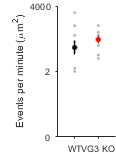

ylim([0 4])
yticks([0:2:4])
yticklabels({'0','2','4000'})
figQuality(gcf, gca, dim);
set(gca,'LooseInset',get(gca,'TightInset')) ;
export_fig('.\EPS Panels\CrenFreq.eps',gcf);


[h, p] = compare2(WTdata.CrenArea, VG3data.CrenArea,{'WT', 'VG3 KO'}, 'Crenation Area (\mum^2)', [1.5 2],[5 12]);

    0.6907



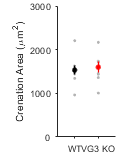

ylim([0 3000]);
yticks([0:1000:3000]);
figQuality(gcf, gca, dim);
set(gca,'LooseInset',get(gca,'TightInset')) ;
export_fig('.\EPS Panels\CrenArea.eps',gcf);

## Color plot

dim = [2.5 0.32];
WTfiles = 'M:\Bergles Lab Data\Projects\In Vivo Imaging and VG3 Paper\In Vitro Experiments\Crenations\WT Littermate\CrenationData_171017_vid_001.mat';
load(WTfiles);
figaa = rainbowRaster(Crens.locs,[420 600]);
figQuality(gcf,gca, dim)
export_fig('C:\Users\Bergles Lab\Desktop\temp\Eps figs\Fig6_WTColor.eps',gcf);
WTlocs = Crens.locs(Crens.locs > 420 & Crens.locs < 600);

VG3files = 'M:\Bergles Lab Data\Projects\In Vivo Imaging and VG3 Paper\In Vitro Experiments\Crenations\VG3 KO\CrenationData_170911_vid_008.mat';
load(VG3files);
figbb = rainbowRaster(Crens.locs,[30 210]);
figQuality(gcf,gca, dim)
export_fig('C:\Users\Bergles Lab\Desktop\temp\Eps figs\Fig6_VG3Color.eps',gcf);
WTlocs = Crens.locs(Crens.locs > 30 & Crens.locs < 210);

## ISC recordings

%data
WTfiles = loadFileList('.\Data\In Vitro Experiments\ISCCurrents\WT Littermate\*.mat');
VG3files = loadFileList('.\Data\In Vitro Experiments\ISCCurrents\VG3 KO\*.mat');

WTISCdata = table()


WTISCdata =

  0×0 empty table



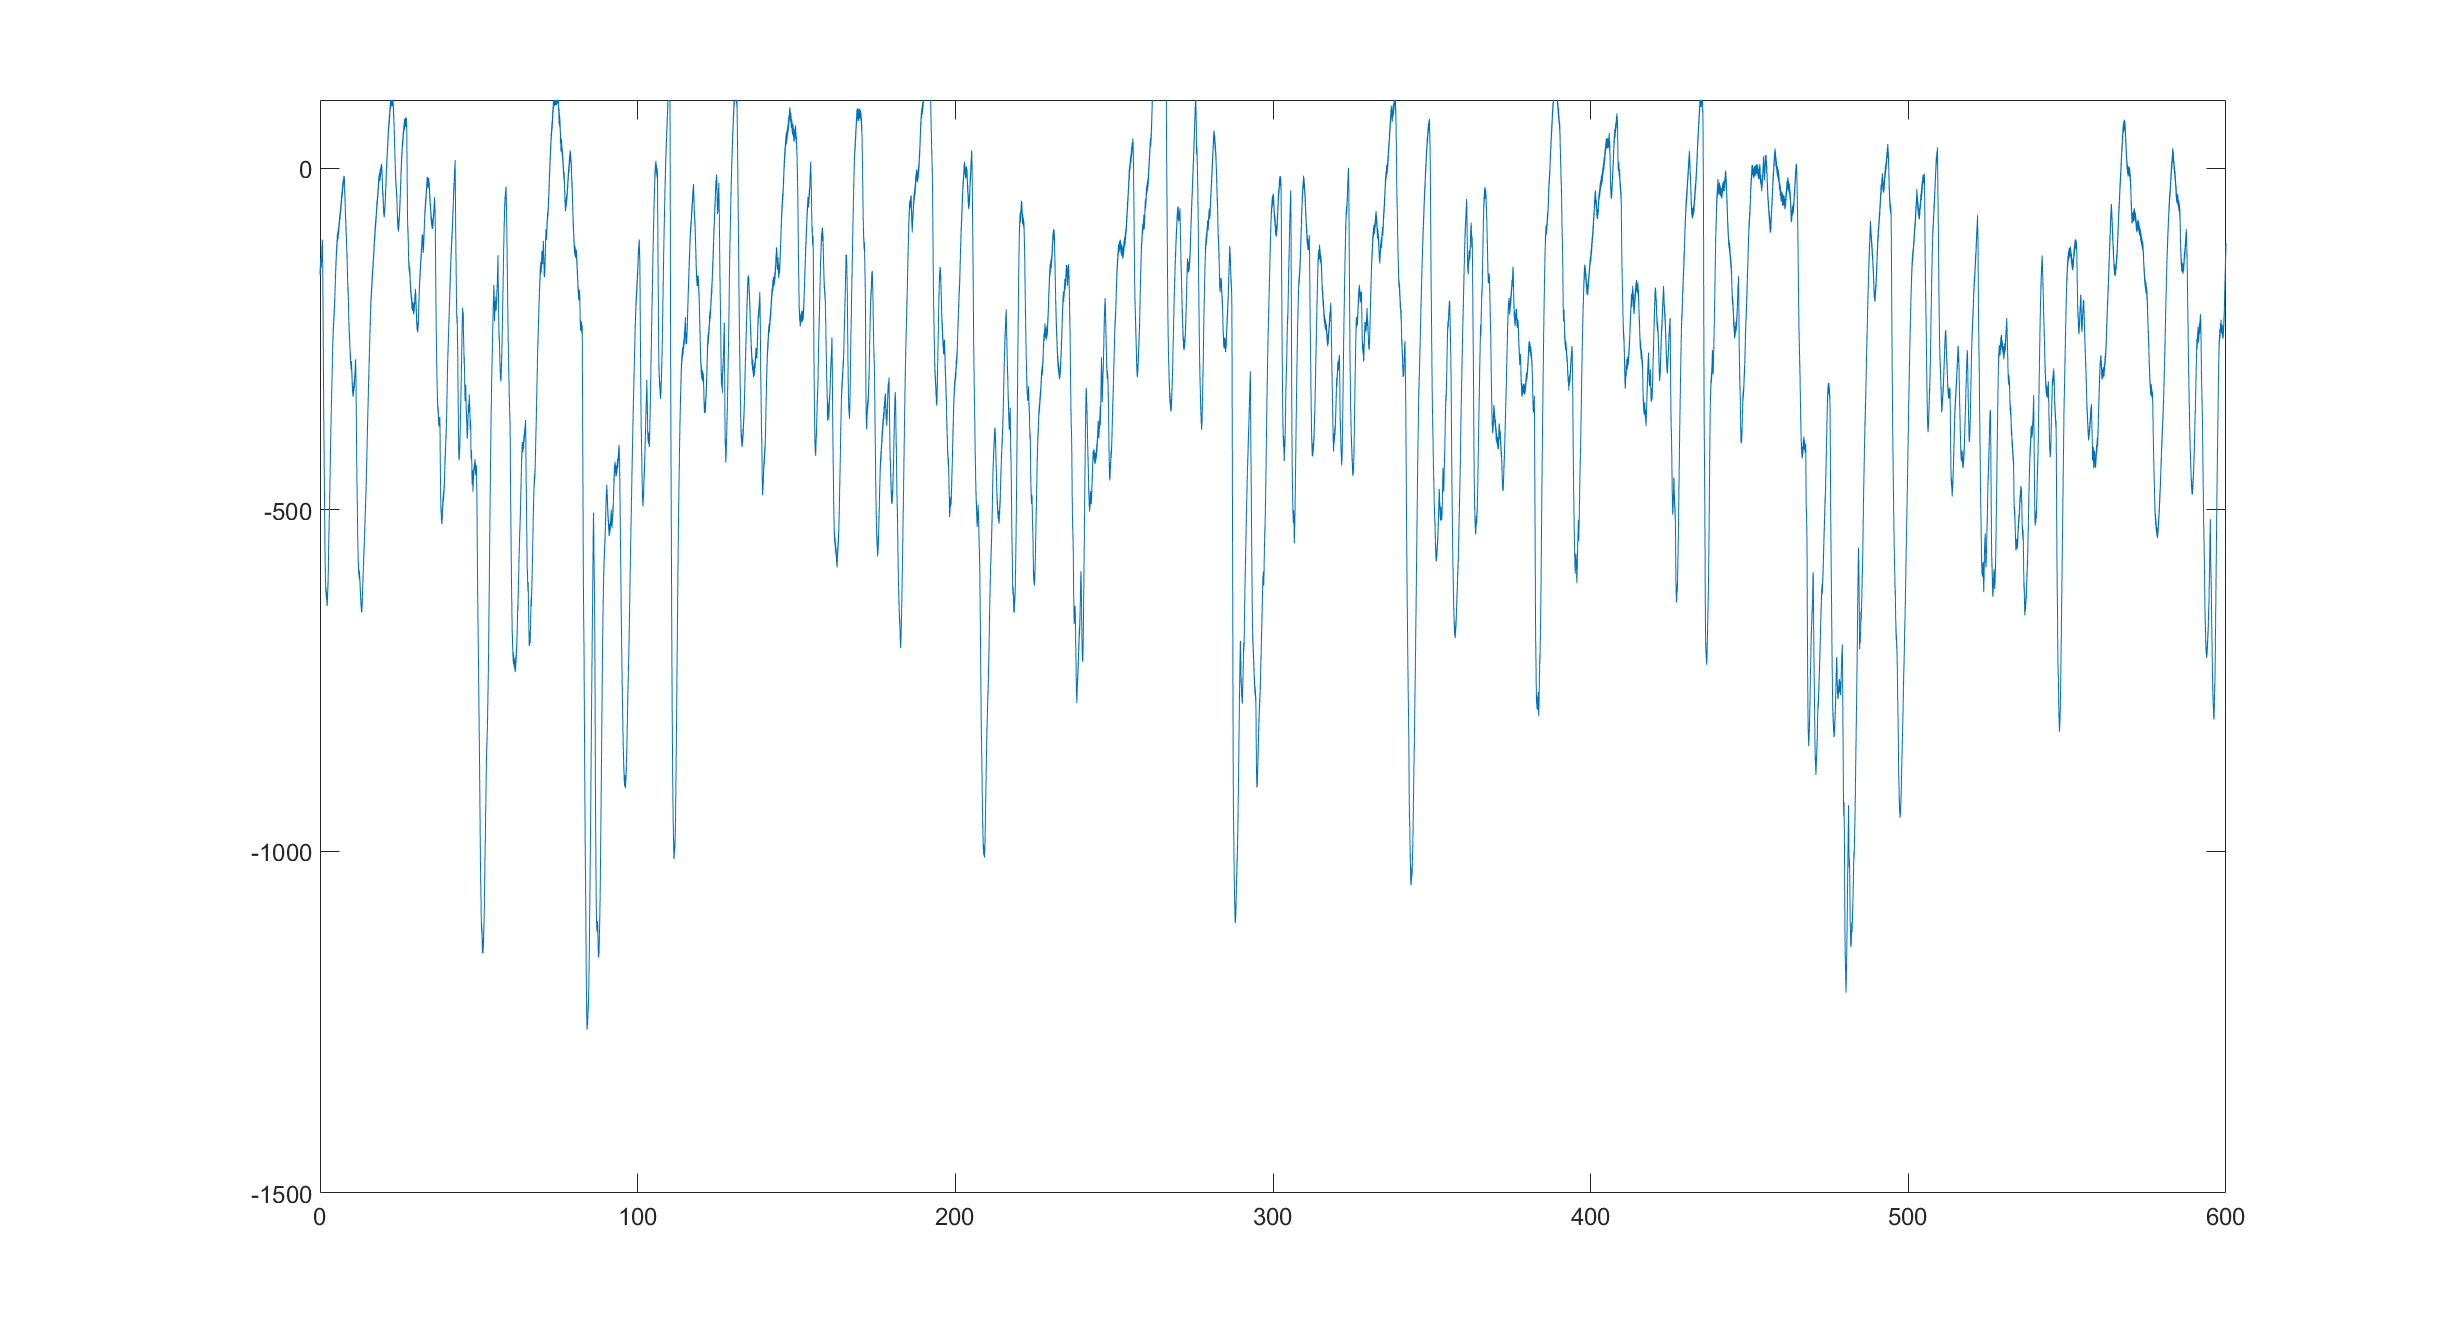

%load data and analyze
for i = 1:size(WTfiles,2)
    load(WTfiles{i})
    ISCstats.time = [0:1/5000:600-1/5000];
    ISCstats.traceBL = ISCstats.traceBL(1:600*5000);
    ISCstats.pks = -findpeaks(-ISCstats.traceBL,ISCstats.time,'MinPeakProminence',std(ISCstats.traceBL,1,1)/4);
    WTISCdata = [WTISCdata; {size(ISCstats.pks,1)/10 mean(ISCstats.pks) ISCstats.integral std(ISCstats.traceBL,1,1)}];
end

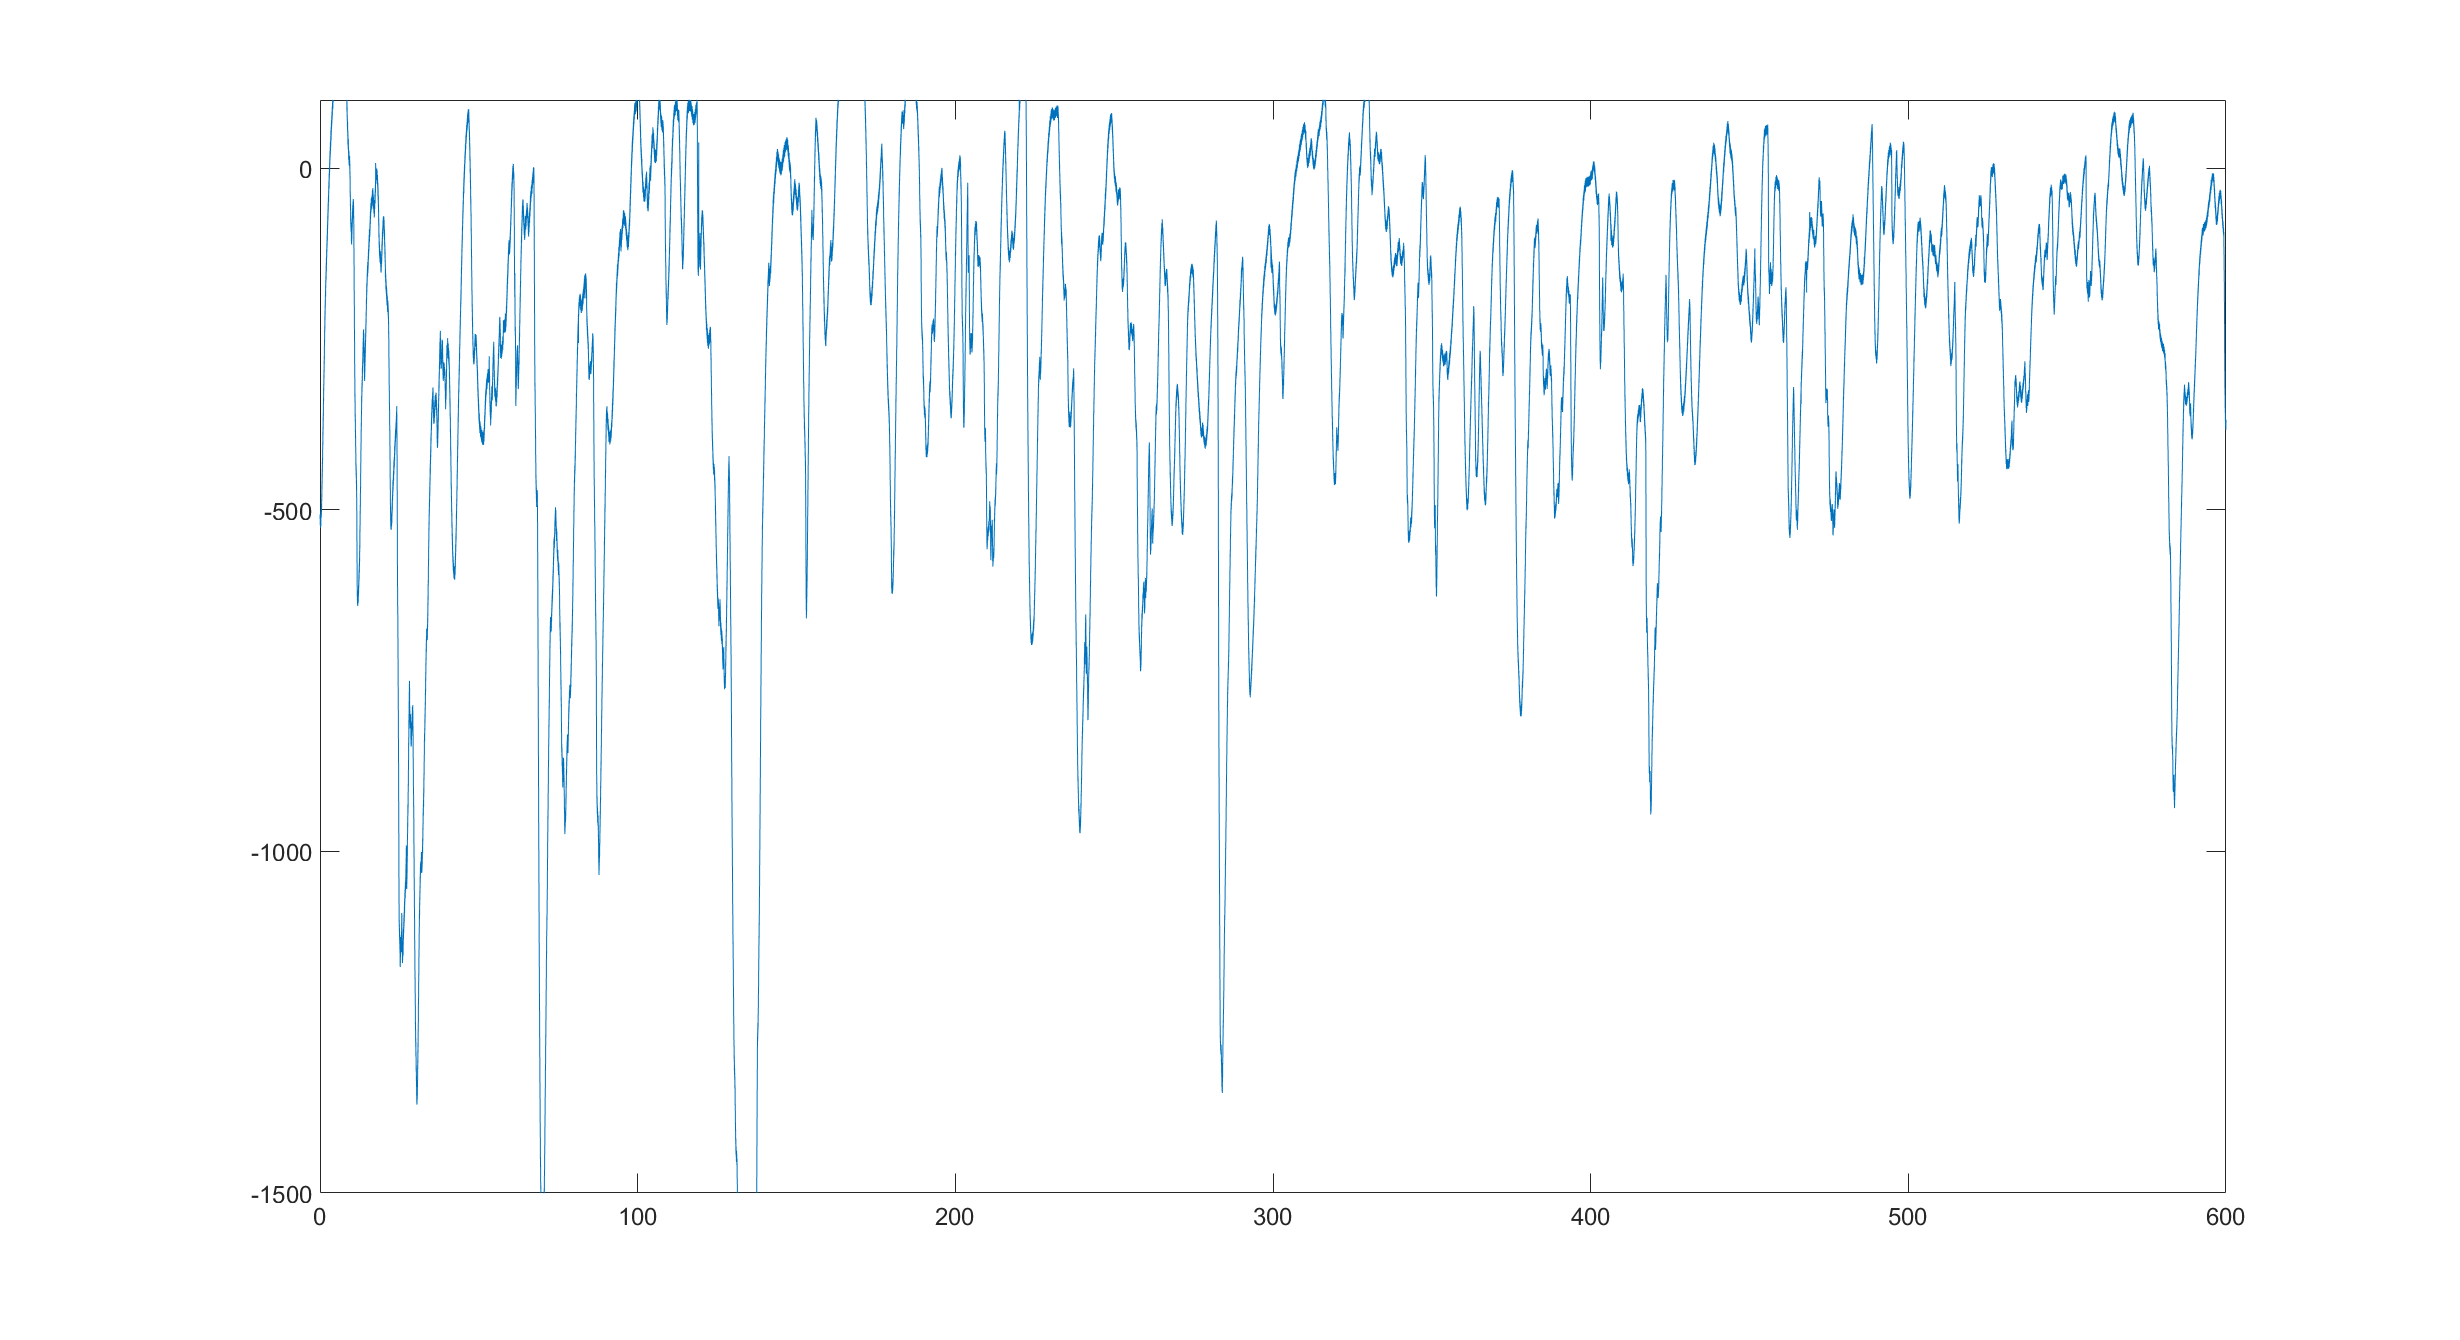

WTISCdata.Properties.VariableNames = {'ISCFreq','meanAmplitude', 'integral', 'std'};

VG3ISCdata = table();
for i = 1:size(VG3files,2)
    load(VG3files{i})
    ISCstats.time = [0:1/5000:600-1/5000];
    ISCstats.traceBL = ISCstats.traceBL(1:600*5000); 
    ISCstats.pks = -findpeaks(-ISCstats.traceBL,ISCstats.time,'MinPeakProminence',std(ISCstats.traceBL,1,1)/4);
    VG3ISCdata = [VG3ISCdata; {size(ISCstats.pks,1)/10 mean(ISCstats.pks) ISCstats.integral std(ISCstats.traceBL,1,1)}];
end

VG3ISCdata.Properties.VariableNames = {'ISCFreq','meanAmplitude', 'integral','std'};


## ISC plot

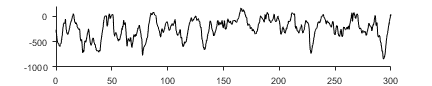

WTdir = 'M:\Bergles Lab Data\Projects\In Vivo Imaging and VG3 Paper\In Vitro Experiments\ISCCurrents\WT Littermate';
VG3dir = 'M:\Bergles Lab Data\Projects\In Vivo Imaging and VG3 Paper\In Vitro Experiments\ISCCurrents\VG3 KO';

%data
WTfiles = returnFiles(dir([WTdir '/*.mat']));
VG3files = returnFiles(dir([VG3dir '/*.mat']));
WTISCfile = WTfiles{2};
load(WTISCfile);
ISCstats.time = [0:1/5000:600-1/5000];
ISCstats.traceBL = ISCstats.traceBL(1:600*5000);
figaa = figure; plot(ISCstats.time, smooth(ISCstats.traceBL,100),'Color','k','LineWidth',0.5); xlim([0 300]); ylim([-1000 200]);
axh = gca;
dim = [4.5 .9];
figQuality(figaa, axh, dim);
export_fig('.\EPS Panels\WTtrace.eps',figaa);

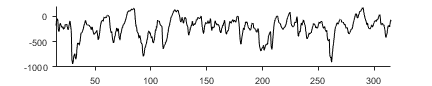


VG3ISCfile = VG3files{4};
load(VG3ISCfile);
ISCstats.time = [0:1/5000:600-1/5000];
ISCstats.traceBL = ISCstats.traceBL(1:600*5000);
figbb = figure; plot(ISCstats.time, smooth(ISCstats.traceBL,100),'Color','k','LineWidth',0.5); xlim([15 315]); ylim([-1000 200]);
axh = gca;
dim = [4.5 .9];
figQuality(figbb, axh, dim);
export_fig('.\EPS Panels\KOtrace.eps',figbb);


dim = [1.0 1.6];
[h, p] = compare2(WTISCdata.Frequency,VG3ISCdata.Frequency,{'WT', 'VG3 KO'}, 'Events per minute (\mum^2)', [1.5 2],[5 12]);

    0.3222



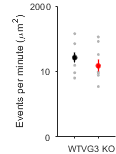

ylim([0 20])
yticks([0:10:20])
yticklabels({'0','10','2000'})
figQuality(gcf, gca, dim);
set(gca,'LooseInset',get(gca,'TightInset')) ;
export_fig('.\EPS Panels\ISCfrequency.eps',gcf);


[h, p] = compare2(-WTISCdata.MeanAmp, -VG3ISCdata.MeanAmp,{'WT', 'VG3 KO'}, 'Mean Amplitude (-pA) (\mum^2)', [1.5 2],[5 12]);

    0.0653



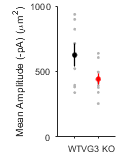

ylim([0 1000]);
yticks([0:500:1000]);
figQuality(gcf, gca, dim);
set(gca,'LooseInset',get(gca,'TightInset')) ;
export_fig('.\EPS Panels\ISCMeanAmp.eps',gcf);

## stats

disp('WT v KO ISC Amp')
[h,p] = ttest2(WTISCdata.MeanAmp,VG3ISCdata.MeanAmp)
disp('WT v KO ISC Freq')
[h,p] = ttest2(WTISCdata.Frequency,VG3ISCdata.Frequency)

disp('WT v KO ISC Amp')
[h,p] = ttest2(WTISCdata.MeanAmp,VG3ISCdata.MeanAmp)
disp('WT v KO ISC Freq')
[h,p] = ttest2(WTISCdata.Frequency,VG3ISCdata.Frequency)

## In vitro calcium imaging

chi = 0.5189

chiShuf = 0.1355

ROIstats = struct with fields:
    baselineFreq: 4.3072
     baselinePks: [43×1 double]
      drugs1Freq: 0
        drug1Pks: [0×1 double]
             chi: 0.5189
         chiShuf: 0.1355


chi = 0.4617

chiShuf = 0.1181

ROIstats = struct with fields:
    baselineFreq: 4.9082
     baselinePks: [49×1 double]
      drugs1Freq: 0
        drug1Pks: [0×1 double]
             chi: 0.4617
         chiShuf: 0.1181


chi = 0.4091

chiShuf = 0.1486

ROIstats = struct with fields:
    baselineFreq: 4.2070
     baselinePks: [42×1 double]
      drugs1Freq: 0.6000
        drug1Pks: [3×1 double]
             chi: 0.4091
         chiShuf: 0.1486


chi = 0.5826

chiShuf = 0.1288

ROIstats = struct with fields:
    baselineFreq: 4.3072
     baselinePks: [43×1 double]
      drugs1Freq: 0
        drug1Pks: [0×1 double]
             chi: 0.5826
         chiShuf: 0.1288


chi = 0.5668

chiShuf = 0.1554

ROIstats = struct with fields:
    baselineFreq: 4.2070
     baselinePks: [42×1 double]
      drugs1Freq: 0
        drug1Pks: [0×1 double]
             chi: 0.5668
         chiShuf: 0.1554


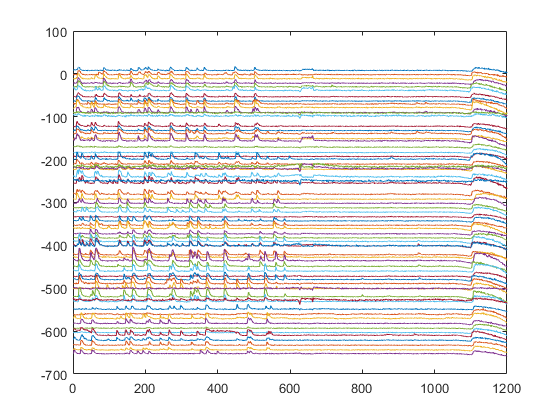

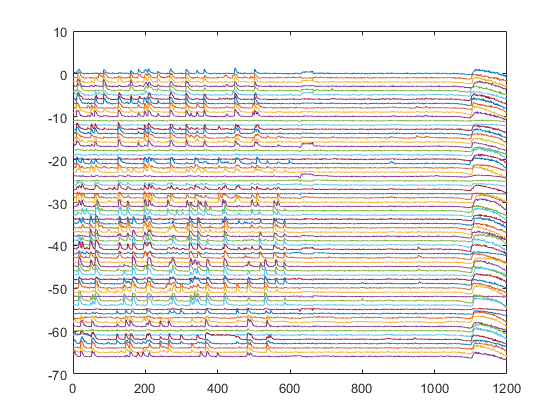

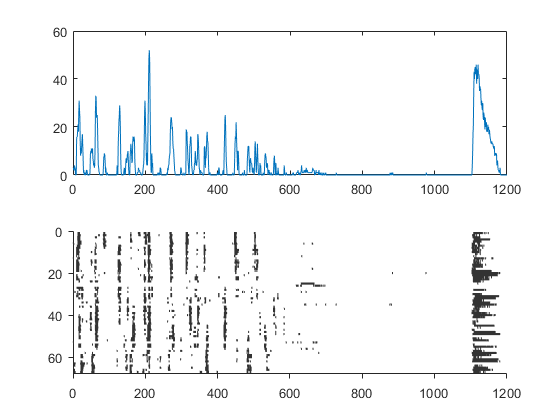

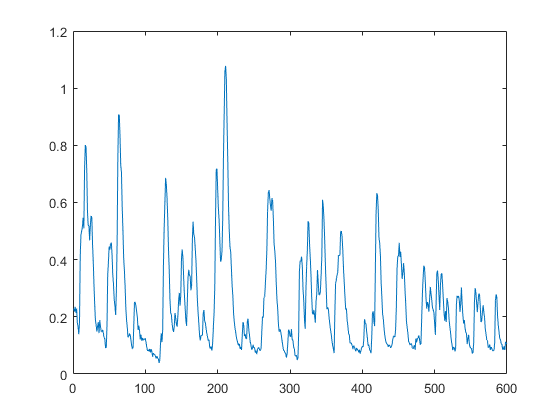

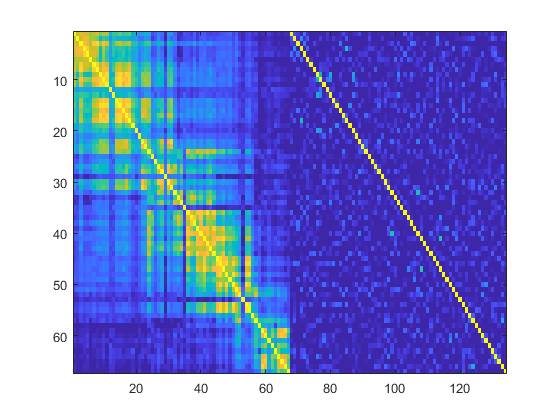

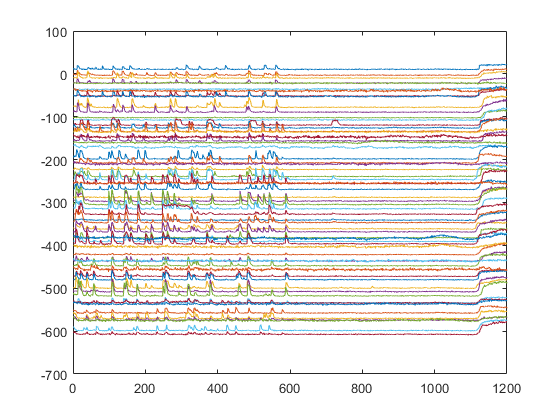

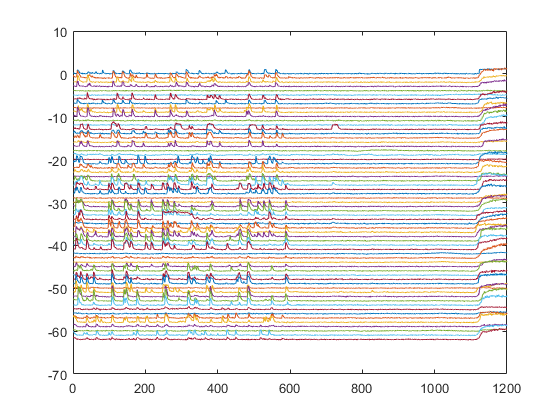

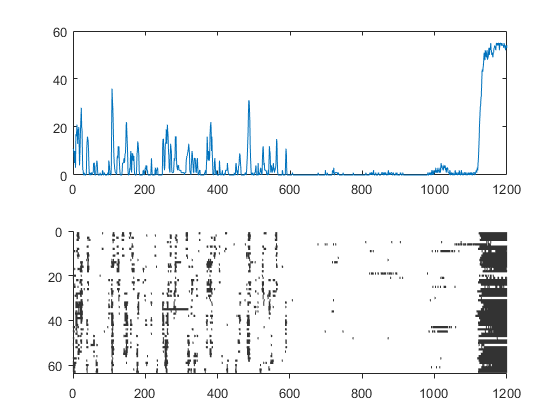


%%files
WT_NBQX = loadFileList('.\Data\In Vitro Experiments\WT + NBQX\*\*Image*.mat');

[m,n] = size(WT_NBQX);

stats = {};
for i = 1:m
   S = load(WT_NBQX{i});
   fieldname = fieldnames(S);
   [ROIstats] = SGN_ROIsignals(S.(fieldname{1}),[1 600], [700 1000])
   stats{i,1} = ROIstats;
end

## VG3KO BBE

chi = 0.4247

chiShuf = 0.1632

ROIstats = struct with fields:
    baselineFreq: 1.3333
     baselinePks: [8×1 double]
      drugs1Freq: 1.5000
        drug1Pks: [9×1 double]
      drugs2Freq: 0.5000
        drug2Pks: [3×1 double]
             chi: 0.4247
         chiShuf: 0.1632


chi = 0.3430

chiShuf = 0.1245

ROIstats = struct with fields:
    baselineFreq: 3.3333
     baselinePks: [20×1 double]
      drugs1Freq: 1.8333
        drug1Pks: [11×1 double]
      drugs2Freq: 0.5000
        drug2Pks: [3×1 double]
             chi: 0.3430
         chiShuf: 0.1245


chi = 0.3217

chiShuf = 0.1155

ROIstats = struct with fields:
    baselineFreq: 3.6667
     baselinePks: [22×1 double]
      drugs1Freq: 5.5000
        drug1Pks: [33×1 double]
      drugs2Freq: 0
        drug2Pks: [0×1 double]
             chi: 0.3217
         chiShuf: 0.1155


chi = 0.3948

chiShuf = 0.1827

ROIstats = struct with fields:
    baselineFreq: 1.6667
     baselinePks: [10×1 double]
      drugs1Freq: 1.5000
        drug1Pks: [9×1 double]
      drugs2Freq: 0
        drug2Pks: [0×1 double]
             chi: 0.3948
         chiShuf: 0.1827


chi = 0.4079

chiShuf = 0.2073

ROIstats = struct with fields:
    baselineFreq: 1
     baselinePks: [6×1 double]
      drugs1Freq: 1.1667
        drug1Pks: [7×1 double]
      drugs2Freq: 0
        drug2Pks: [0×1 double]
             chi: 0.4079
         chiShuf: 0.2073


chi = 0.2668

chiShuf = 0.1392

ROIstats = struct with fields:
    baselineFreq: 2.8333
     baselinePks: [17×1 double]
      drugs1Freq: 3
        drug1Pks: [18×1 double]
      drugs2Freq: 0.6667
        drug2Pks: [4×1 double]
             chi: 0.2668
         chiShuf: 0.1392


chi = 0.3683

chiShuf = 0.1649

ROIstats = struct with fields:
    baselineFreq: 2.5000
     baselinePks: [15×1 double]
      drugs1Freq: 0.5000
        drug1Pks: [3×1 double]
      drugs2Freq: 0
        drug2Pks: [0×1 double]
             chi: 0.3683
         chiShuf: 0.1649


chi = 0.2201

chiShuf = 0.1488

ROIstats = struct with fields:
    baselineFreq: 3.8333
     baselinePks: [23×1 double]
      drugs1Freq: 3.6667
        drug1Pks: [22×1 double]
      drugs2Freq: 0.8333
        drug2Pks: [5×1 double]
             chi: 0.2201
         chiShuf: 0.1488


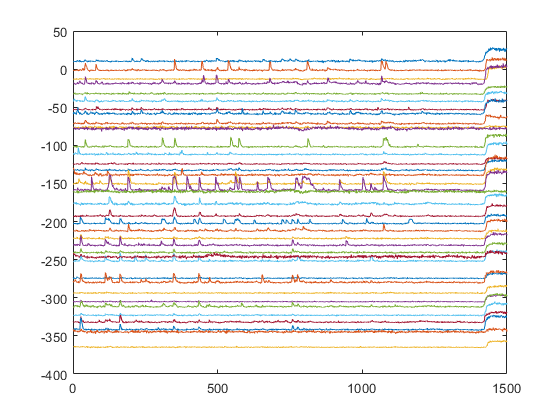

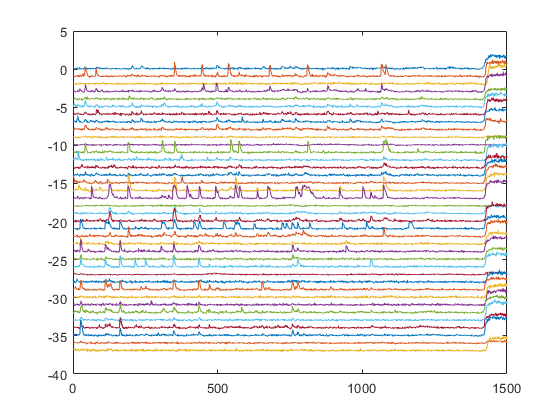

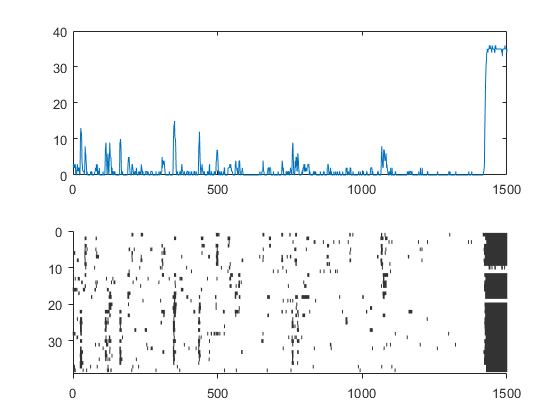

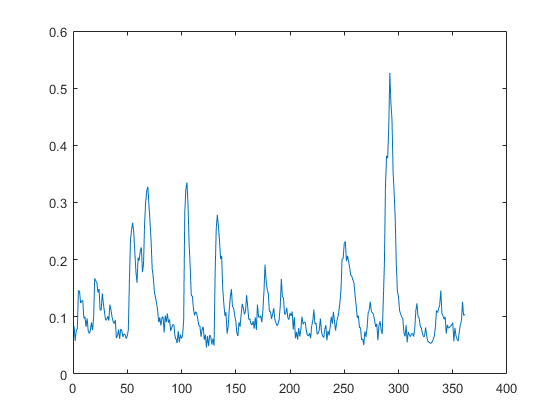

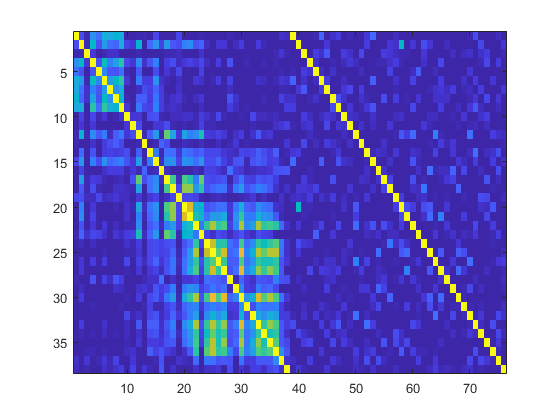

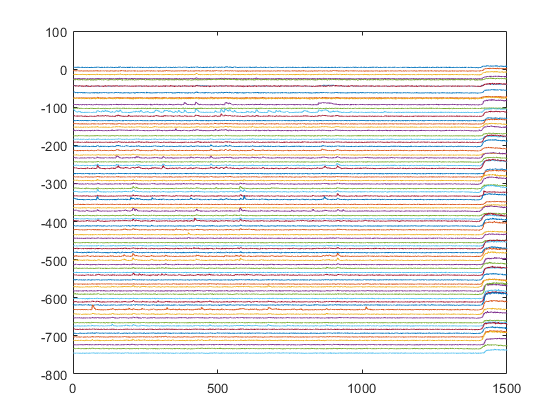

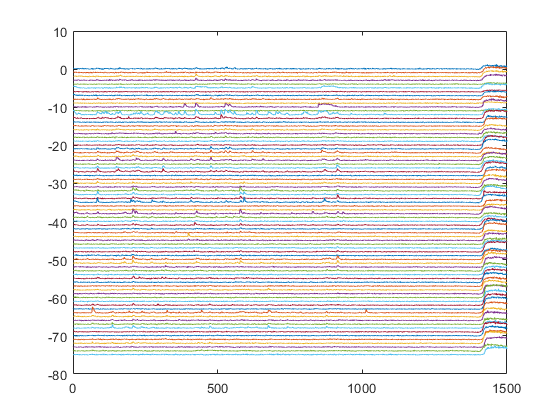

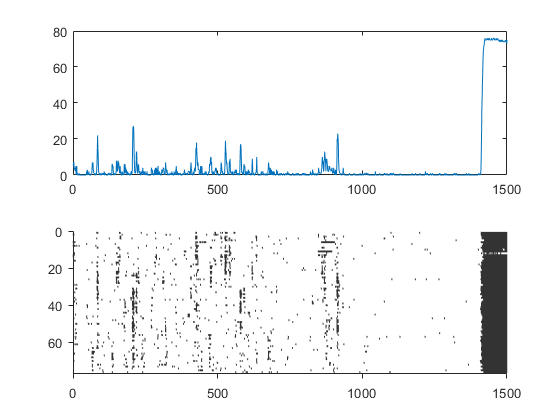

VG3_BBE = loadFileList('.\Data\In Vitro Experiments\VG3KO + NBQX + BBE\*\*Image*.mat');

[m,n] = size(VG3_BBE);

VG3stats = {};
for i = 1:m
   S = load(VG3_BBE{i});
   fieldname = fieldnames(S);
   [ROIstats, SGNdFoF] = SGN_ROIsignals(S.(fieldname{1}),[60 420], [480 840], [900 1260]);
   ROIstats
   VG3stats(i,:) = {ROIstats SGNdFoF};
end

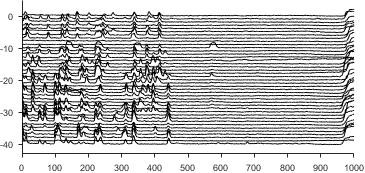

%Example Plots
WT_NBQX = loadFileList('.\Data\In Vitro Experiments\WT + NBQX\*\*V3.mat');

load(WT_NBQX{2});
offset = 1;
j=0;
figure;
for i=1:eventStruct.numCells 
    if eventStruct.SGN(i).keepTrace && j < 41
        plot(smooth(eventStruct.SGN(i).dFoF(150:end) - j*offset),'Color','k'); hold on;
        j = j+1;
    end
end
xlim([0 1000])
ylim([-43 5])
figQuality(gcf, gca, [3.8 1.8]);
set(gca,'LooseInset',get(gca,'TightInset')) ;
export_fig('.\EPS Panels\WT_SGNs.eps',gcf);

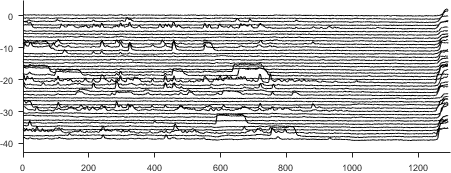


VG3_NBQX = loadFileList('.\Data\In Vitro Experiments\VG3KO + NBQX + BBE\*\*V3.mat');

load(VG3_NBQX{8});
offset = 1;
j=0;
figure;
for i=1:eventStruct.numCells
    if eventStruct.SGN(i).keepTrace && j < 40
        plot(smooth(eventStruct.SGN(i).dFoF(150:end) - j*offset),'Color','k'); hold on;
        j = j+1;
    end
end
xlim([0 1300])
ylim([-43 5])
figQuality(gcf, gca, [4.7 1.8]);
set(gca,'LooseInset',get(gca,'TightInset')) ;
export_fig('.\EPS Panels\VG3_SGNs.eps',gcf);

## plots

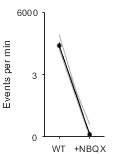

%%frequency
f1 = figure;
gray = [0.7 0.7 0.7];
WTpeaks = [];
WTstatBlock = [];
WTpeaksavg = [];
[m,n] = size(WT_NBQX);
for i = 1:m
    load(WT_NBQX{i})
    WTstatBlock(i,:) = [stats{i,1}.baselineFreq stats{i,1}.drugs1Freq];
    WTpeaks = [WTpeaks; stats{i,1}.baselinePks];
    WTpeaksavg(i) = mean(stats{i,1}.baselinePks);
    %plot(1,stats{i,1}.baselineFreq,'.','Color',gray); hold on;
    %plot(1.5,stats{i,1}.drugs1Freq,'.','Color',gray); 
    line([1 1.5],[stats{i,1}.baselineFreq stats{i,1}.drugs1Freq],'Color',gray); hold on;
end

errorbar(1, mean(WTstatBlock(:,1)), std(WTstatBlock(:,1),[],1)/sqrt(size(WTstatBlock,1)),'LineStyle', 'none','Color','k','CapSize',0,'Marker','.','MarkerSize',10);
errorbar(1.5, mean(WTstatBlock(:,2)), std(WTstatBlock(:,2),[],1)/sqrt(size(WTstatBlock,1)),'LineStyle', 'none','Color','k','CapSize',0,'Marker','.','MarkerSize',10);
line([1 1.5],[mean(WTstatBlock(:,1)) mean(WTstatBlock(:,2))],'Color','k');
xlim([0.75 1.75]);
xticks([1 1.5]);
xticklabels({'WT', '+NBQX'});
ylim([0 6]);
yticks([0 3 6]);
yticklabels({'0','3','6000'});
ylabel('Events per min');
figQuality(gcf,gca,[1 1.6]);
export_fig(['.\EPS Panels\WTNBQX_group.eps'], '-eps', '-nocrop')


figure;
VG3peaks = [];
VG3peaksAvg = [];
[m,n] = size(VG3_BBE);
statBlock = []'


statBlock =

     []



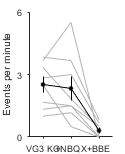

for i = 1:m
    statBlock(i,:) = [VG3stats{i,1}.baselineFreq VG3stats{i,1}.drugs1Freq VG3stats{i,1}.drugs2Freq];
    VG3peaks = [VG3peaks; VG3stats{i,1}.baselinePks];
    VG3peaksAvg(i) = mean(VG3stats{i,1}.baselinePks);
    %plot(2,VG3stats{i,1}.baselineFreq,'.','Color',gray); hold on;
    %plot(2.5,VG3stats{i,1}.drugs1Freq,'.','Color',gray); 
    %plot(3,VG3stats{i,1}.drugs2Freq,'.','Color',gray); 
    line([1 1.5],[VG3stats{i,1}.baselineFreq VG3stats{i,1}.drugs1Freq],'Color',gray); hold on;
    line([1.5 2],[VG3stats{i,1}.drugs1Freq VG3stats{i,1}.drugs2Freq],'Color',gray);
end

errorbar(1, mean(statBlock(:,1)), std(statBlock(:,1),[],1)/sqrt(size(statBlock,1)),'LineStyle', 'none','Color','k','CapSize',0,'Marker','.','MarkerSize',10);
errorbar(1.5, mean(statBlock(:,2)), std(statBlock(:,2),[],1)/sqrt(size(statBlock,1)),'LineStyle', 'none','Color','k','CapSize',0,'Marker','.','MarkerSize',10);
errorbar(2, mean(statBlock(:,3)), std(statBlock(:,3),[],1)/sqrt(size(statBlock,1)),'LineStyle', 'none','Color','k','CapSize',0,'Marker','.','MarkerSize',10);
line([1 1.5],[mean(statBlock(:,1)) mean(statBlock(:,2))],'Color','k','MarkerSize',10);
line([1.5 2],[mean(statBlock(:,2)) mean(statBlock(:,3))],'Color','k','MarkerSize',10);
xlim([0.75 2.25]);
xticks([1 1.5 2]);
xticklabels({'VG3 KO', '+NBQX', '+BBE'});
ylim([0 6]);
yticks([0 3 6]);
ylabel('Events per minute');
figQuality(gcf,gca,[1.3 1.6]);
export_fig(['.\EPS Panels\VG3_NBQX_BBEgroup.eps'], '-eps', '-nocrop')


[h,p] = ttest2(statBlock(:,1),WTstatBlock(:,1))

h = 1

p = 0.0035

[h,p] = ttest(WTstatBlock(:,2),WTstatBlock(:,1))

h = 1

p = 3.2445e-05

## SUm Fig

figure;
[m,n] = size(WT_NBQX);
for i = 1:m
    WTstatBlock(i,:) = [stats{i,1}.baselineFreq stats{i,1}.drugs1Freq];
    WTpeaks = [WTpeaks; stats{i,1}.baselinePks];
    WTpeaksavg(i) = mean(stats{i,1}.baselinePks);
    %plot(1,stats{i,1}.baselineFreq,'.','Color',gray); hold on;
    %plot(1.5,stats{i,1}.drugs1Freq,'.','Color',gray); 
    plot(2.5*ones(1,m),stats{i,1}.baselineFreq,'Color',gray,'MarkerSize',5,'Marker','.'); hold on;
end

%errorbar(2.5, mean(WTstatBlock(:,1)), std(WTstatBlock(:,1),[],1)/sqrt(size(WTstatBlock,1)),'LineStyle', 'none','Color','k','CapSize',0,'Marker','.','MarkerSize',10);
ylim([0 6]);
yticks([0 3 6]);
ylabel('Events per min');
figQuality(gcf,gca,[1 1.6]);

VG3peaks = [];
VG3peaksAvg = [];
[m,n] = size(VG3_BBE);
VG3statBlock = []'


VG3statBlock =

     []



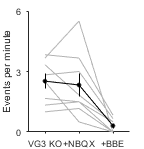

for i = 1:m
    VG3statBlock(i,:) = [VG3stats{i,1}.baselineFreq VG3stats{i,1}.drugs1Freq VG3stats{i,1}.drugs2Freq];
    VG3peaks = [VG3peaks; VG3stats{i,1}.baselinePks];
    VG3peaksAvg(i) = mean(VG3stats{i,1}.baselinePks);
    %plot(2,VG3stats{i,1}.baselineFreq,'.','Color',gray); hold on;
    %plot(2.5,VG3stats{i,1}.drugs1Freq,'.','Color',gray); 
    %plot(3,VG3stats{i,1}.drugs2Freq,'.','Color',gray); 
    line([1 1.5],[VG3stats{i,1}.baselineFreq VG3stats{i,1}.drugs1Freq],'Color',gray); hold on;
    line([1.5 2],[VG3stats{i,1}.drugs1Freq VG3stats{i,1}.drugs2Freq],'Color',gray);
end

errorbar(1, mean(VG3statBlock(:,1)), std(VG3statBlock(:,1),[],1)/sqrt(size(statBlock,1)),'LineStyle', 'none','Color','k','CapSize',0,'Marker','.','MarkerSize',10);
errorbar(1.5, mean(VG3statBlock(:,2)), std(VG3statBlock(:,2),[],1)/sqrt(size(statBlock,1)),'LineStyle', 'none','Color','k','CapSize',0,'Marker','.','MarkerSize',10);
errorbar(2, mean(VG3statBlock(:,3)), std(VG3statBlock(:,3),[],1)/sqrt(size(statBlock,1)),'LineStyle', 'none','Color','k','CapSize',0,'Marker','.','MarkerSize',10);
line([1 1.5],[mean(VG3statBlock(:,1)) mean(VG3statBlock(:,2))],'Color','k','MarkerSize',10);
line([1.5 2],[mean(VG3statBlock(:,2)) mean(VG3statBlock(:,3))],'Color','k','MarkerSize',10);
xlim([0.75 2.25]);
xticks([1 1.5 2]);
xticklabels({'VG3 KO', '+NBQX', '+BBE'});
ylim([0 6]);
yticks([0 3 6]);
ylabel('Events per minute');
figQuality(gcf,gca,[1.5 1.55]);
export_fig(['.\EPS Panels\VG3_NBQX_BBEgroup.eps'], '-eps', '-nocrop')



[h,p] = ttest2(VG3statBlock(:,1),WTstatBlock(:,1))

h = 1

p = 0.0035

## other fig

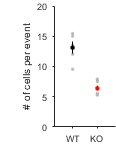


figure;
[m] = size(WTpeaksavg,2);
m2 = size(VG3peaksAvg,2);
plot(ones(1,m),WTpeaksavg,'.','Color',gray); hold on;
plot(ones(1,m2)*2,VG3peaksAvg,'.','Color',gray);
meanWT2 = mean(WTpeaksavg);
meanVG32 = mean(VG3peaksAvg);
stderrWT2 = std(WTpeaksavg,1,2)/sqrt(m);
stderrVG32 = std(VG3peaksAvg)/sqrt(m2);
errorbar(1, meanWT2, stderrWT2,'LineStyle', 'none','Color','k','CapSize',0,'Marker','.','MarkerSize',10);
errorbar(2, meanVG32, stderrVG32,'LineStyle', 'none','Color','r','CapSize',0,'Marker','.','MarkerSize',10);

xlim([.25 2.75]);
xticks([1 2]);
xticklabels({'WT' 'KO'});
ylim([0 20]);
ylabel('# of cells per event');
figQuality(gcf, gca, [0.75 1.5]);
set(gca,'LooseInset',get(gca,'TightInset'));
export_fig('.\EPS Panels\VG3_WT_group.eps', '-eps', '-nocrop')


[h,p] = ttest2(WTpeaksavg,VG3peaksAvg)

h = 1

p = 2.8154e-05

## Stats


%repeated measures ANOVA
[m,n] = size(VG3_BBE);
statTable = table(ones(m,1),statBlock(:,1),statBlock(:,2),statBlock(:,3));
statTable.Properties.VariableNames = {'AnimalNum','Baseline','NBQX','NBQX_BBE'}; rm = fitrm(statTable,'Baseline-NBQX_BBE~1')

rm =   RepeatedMeasuresModel with properties:

   Between Subjects:
         BetweenDesign: [8×4 table]
         ResponseNames: {'Baseline'  'NBQX'  'NBQX_BBE'}
    BetweenFactorNames: {1×0 cell}
          BetweenModel: '1'

   Within Subjects:
          WithinDesign: [3×1 table]
     WithinFactorNames: {'Time'}
           WithinModel: 'separatemeans'

   Estimates:
          Coefficients: [1×3 table]
            Covariance: [3×3 table]


rm = fitrm(statTable,'Baseline-NBQX_BBE~1');
r = ranova(rm); %this is signifcant
multcompare(rm,'Time','ComparisonType','dunn-sidak') %baseline and NBQX NS, baseline and NBQX vs BBE is significant

ans = 6×7 table
    Time_1    Time_2    Difference    StdErr      pValue       Lower      Upper  
    ______    ______    __________    _______    _________    _______    ________

    1         2          0.1875        0.4112      0.96146    -1.0936      1.4686
    1         3          2.2083       0.35038    0.0012089     1.1168      3.2999
    2         1         -0.1875        0.4112      0.96146    -1.4686      1.0936
    2         3          2.0208       0.56206     0.026149    0.26979      3.7719
    3         1         -2.2083       0.35038    0.0012089    -3.2999     -1.1168
    3         2         -2.0208       0.56206     0.026149    -3.7719    -0.26979


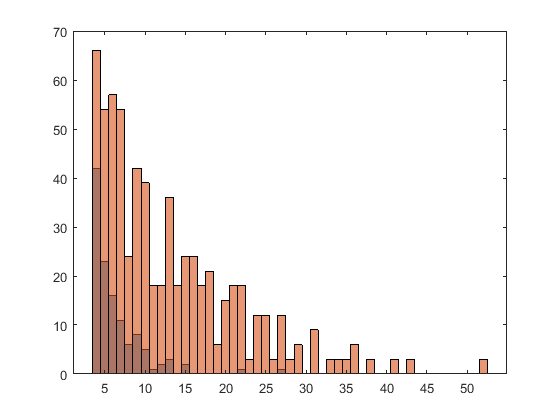




figure; histogram(VG3peaks); hold on; histogram(WTpeaks);

mean(VG3peaks)

ans = 6.4380

mean(WTpeaks)

ans = 13.0959

figure;
%%frequency

## Event width histograms

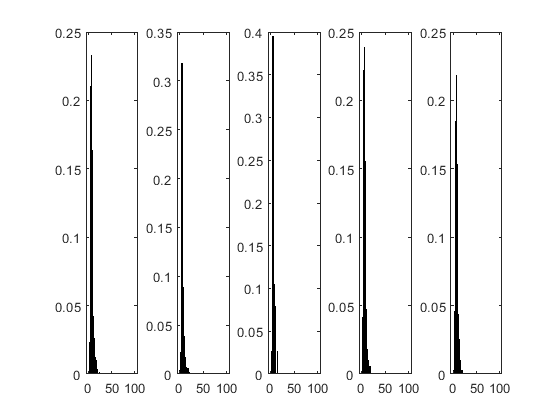

WTdir = '.\Data\In Vitro Experiments\WT + NBQX\*\*V3.mat';
WTfiles = loadFileList(WTdir);

edges = [0:1:30 100];
WTgroup = [];
WTgroupMean = [];
WTBinCounts = [];
figure;
for i = 1:size(WTfiles,1)
    load(WTfiles{i});
    subplot(1,size(WTfiles,1),i);
    WThisto = histogram(eventStruct.groupWidths,edges,'FaceColor','k','Normalization','pdf'); hold on;
    WTBinCounts(i,:) = WThisto.BinCounts;
    WTgroupMean = [WTgroupMean; mean(eventStruct.groupWidths)];
    WTgroup = [WTgroup; eventStruct.groupWidths];
end

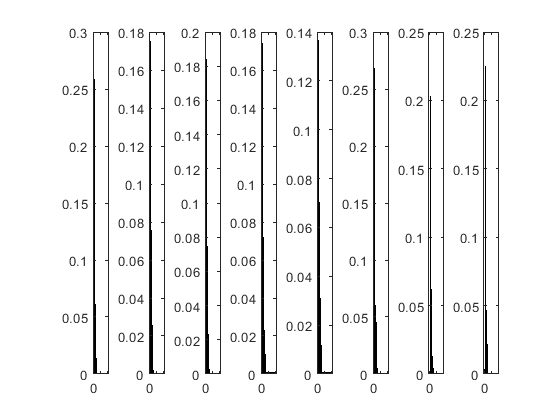


VG3dir = '.\Data\In Vitro Experiments\VG3KO + NBQX + BBE\*\*V3.mat';
VG3files = loadFileList(VG3dir);

edges = [0:1:30 100];
VG3group=[];
VG3groupMean = [];
VG3BinCounts = [];
figure;
for i = 1:size(VG3files,1)
    load(VG3files{i});
    subplot(1,size(VG3files,1),i);
    histoVG3 = histogram(eventStruct.groupWidths,edges,'FaceColor','r','Normalization','pdf'); hold on;
    VG3BinCounts(i,:) = histoVG3.BinCounts;
    VG3groupMean = [VG3groupMean; mean(eventStruct.groupWidths)];
    VG3group = [VG3group; eventStruct.groupWidths];
end

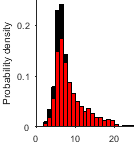


figure;
load(WTfiles{1});
histogram(WTgroup,edges,'FaceColor','k','Normalization','pdf','FaceAlpha',1); hold on;
load(VG3files{4});
histoVG3 = histogram(VG3group,edges,'FaceColor','r','Normalization','pdf','FaceAlpha',1);
%xlabel('Full width at half maximum (s)');
xlim([0 25]);
xticks([0:10:50]);
ylabel('Probability density');
yticks([0 .1 .2]);

figQuality(gcf,gca,[1.4 1.5]);
set(gca,'LooseInset',get(gca,'TightInset'));
export_fig(['.\EPS Panels\VG3_WT_fullwidth.eps'], '-eps', '-nocrop');


figure;
meanWT2 = mean(WTgroupMean);
m = size(WTgroupMean,1);
meanKO2 = mean(VG3groupMean);
m2 = size(VG3groupMean,1);
stdWT2 = std(WTgroupMean,1,1)/sqrt(m);
stdKO2 = std(VG3groupMean,1,1)/sqrt(m2);
plot(ones(1,m),WTgroupMean,'.','Color',grey,'MarkerFaceColor',grey); hold on
errorbar(1,meanWT2,stdWT2,'LineStyle', 'none','Color','k','CapSize',0,'Marker','.','MarkerSize',10);
plot(2*ones(1,m2),VG3groupMean,'.','Color',grey,'MarkerFaceColor',grey);
errorbar(2,meanKO2,stdKO2,'LineStyle', 'none','Color','r','CapSize',0,'Marker','.','MarkerSize',10);
ylabel('Mean FWHM (s)');
xticks([1 2]);
xticklabels({'WT' 'VG3 KO'});
xlim([0.25 2.75]);
ylim([0 15]);
yticks([0 7.5 15])
figQuality(gcf, gca, [0.75 1.5]);
set(gca,'LooseInset',get(gca,'TightInset'));
export_fig('.\EPS Panels\FWHM.eps',gcf);


## group histogram


%get values for sterr
edges = [0:1:31]

edges =      0     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30    31


WTnormBinCount = [];
for i=1:size(WTBinCounts,1)
    WTpdf = histogram('BinEdges',edges,'BinCounts',WTBinCounts(i,:),'Normalization','pdf','EdgeColor','k','FaceAlpha',1);
    WTnormBinCount(i,:) = WTpdf.Values;
end

edges = [0:1:31]

edges =      0     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30    31


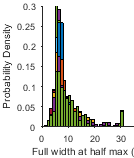

VG3normBinCount = [];
for i=1:size(WTBinCounts,1)
    WTpdf = histogram('BinEdges',edges,'BinCounts',VG3BinCounts(i,:),'Normalization','pdf','EdgeColor','k','FaceAlpha',1);
    VG3normBinCount(i,:) = WTpdf.Values;
end

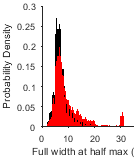


edgesX = [0.5:1:30.5];
figure;
WTpdf = histogram('BinEdges',edges,'BinCounts',mean(WTBinCounts,1),'Normalization','pdf','EdgeColor','k','FaceColor','k','FaceAlpha',1); hold on;
VG3pdf = histogram('BinEdges',edges,'BinCounts',mean(VG3BinCounts,1),'Normalization','pdf','EdgeColor','r','FaceColor','r','FaceAlpha',1);
WTsterr = std(WTnormBinCount,[],1)/sqrt(size(WTnormBinCount,1));
line([edgesX; edgesX],[WTpdf.Values + WTsterr;WTpdf.Values - WTsterr],'Color','k');
VG3sterr = std(VG3normBinCount,[],1)/sqrt(size(VG3normBinCount,1));
line([edgesX; edgesX],[VG3pdf.Values + VG3sterr;VG3pdf.Values - VG3sterr],'Color','r');
xlim([0 35]);
ylim([0 .30]);
ylabel('Probability Density');
xlabel('Full width at half max (s)')
figQuality(gcf, gca, [1.4 1.65]);
set(gca,'LooseInset',get(gca,'TightInset'));
export_fig('.\EPS Panels\FWHM_group.eps',gcf);

## chi


f3 = figure;
gray = [0.7 0.7 0.7];
VG3peaks = [];
statBlock2 = [];
[m,n] = size(VG3_BBE)
for i = 1:m
    statBlock2(i,:) = [VG3stats{i,1}.chi VG3stats{i,1}.chiShuf];
    plot(2,VG3stats{i,1}.chi,'.','Color',gray); hold on;
    plot(2.5,VG3stats{i,1}.chiShuf,'.','Color',gray); 
end
[m,n] = size(WT_NBQX);
statBlock3 = [];
for i = 1:m
    statBlock3(i,:) = [stats{i,1}.chi stats{i,1}.chiShuf];
    plot(1,stats{i,1}.chi,'.','Color',gray); hold on;
    plot(1.5,stats{i,1}.chiShuf,'.','Color',gray); 
end
errorbar(1, mean(statBlock3(:,1)), std(statBlock3(:,1),[],1)/sqrt(size(statBlock3,1)),'LineStyle', 'none','Color','k','CapSize',0,'Marker','.','MarkerSize',10);
errorbar(2, mean(statBlock2(:,1)), std(statBlock2(:,1),[],1)/sqrt(size(statBlock2,1)),'LineStyle', 'none','Color','k','CapSize',0,'Marker','.','MarkerSize',10);
errorbar(1.5, mean(statBlock3(:,2)), std(statBlock3(:,2),[],1)/sqrt(size(statBlock3,1)),'LineStyle', 'none','Color','k','CapSize',0,'Marker','.','MarkerSize',10);
errorbar(2.5, mean(statBlock2(:,2)), std(statBlock2(:,2),[],1)/sqrt(size(statBlock2,1)),'LineStyle', 'none','Color','k','CapSize',0,'Marker','.','MarkerSize',10);

xlim([0.75 2.75]);
xticks([1 1.5 2 2.5]);
ylim([0 1]);
yticks([0 0.5 1]);
ylabel({'Synchrony Index (\Chi)'})
xticklabels({'WT','WT','VG3','VG3'});
set(gca,'FontSize',8)
f3.Units = 'inches';
f3.Position = [0 0 2 2];
set(gca,'LooseInset',get(gca,'TightInset'));
figQuality(gcf,gca,[1.4 1.55]);
export_fig(['.\EPS Panels\VG3_WT_Chi_group.eps'], '-eps', '-nocrop')


%%stats

[~,~,stats2] = anovan([statBlock3(:,1); statBlock2(:,1); statBlock3(:,2); statBlock2(:,2);],[1 1 1 1 1 2 2 2 2 2 2 2 3 3 3 3 3 4 4 4 4 4 4 4]');
multcompare(rm,'Time','ComparisonType','dunn-sidak') %baseline and NBQX NS, baseline and NBQX vs BBE is significant


## individual VG3 BBE plot

clear all;
file = '.\Data\In Vitro Experiments\VG3KO + NBQX + BBE\170914_Image15_VG3KO_NBQX_BBE\SGNEventsV3.mat';
load(file);

data = [];
for i=1:eventStruct.numCells
    if eventStruct.SGN(i).keepTrace
        data = [data eventStruct.SGN(i).dFoF];
    end
end

SGNworking = data;
vars = var(SGNworking);
bottom = prctile(vars,15,2);
top = prctile(vars,90,2);
SGNworking = SGNworking(:, vars > bottom & vars < top)
[m,n] = size(SGNworking);
smdFoF = smooth(SGNworking);
SGNdFoF = reshape(smdFoF,m,n);

offset = [];
for i=2:51
    offset(:,i) = SGNdFoF(:,i) + (i-1)*1.2;
end
f=figure; plot(offset,'k');
xlim([0 1440]);
ylim([-1 65]);
box off;
figQuality(gcf,gca,[5.0 1.7])
set(gca,'LooseInset',get(gca,'TightInset'));
export_fig(['.\EPS Panels\VG3_NBQX_BBEex.eps'], '-eps', '-nocrop')






## individual WT NBQX plot

file = '.\Data\In Vitro Experiments\WT + NBQX\Image16_WT_NBQX\SGNEventsV3.mat'
load(file);

data = [];
for i=1:eventStruct.numCells
    if eventStruct.SGN(i).keepTrace
        data = [data eventStruct.SGN(i).dFoF];
    end
end

SGNworking = data;
% vars = var(SGNworking);
% bottom = prctile(vars,15,2);
% top = prctile(vars,90,2);
% SGNworking = SGNworking(:, vars > bottom & vars < top)
[m,n] = size(SGNworking);
smdFoF = smooth(SGNworking);
SGNdFoF = reshape(smdFoF,m,n);

offset = [];
for i=1:n
    offset(:,i) = SGNdFoF(:,i) + (i-1)*1.2;
end
f=figure; plot(offset,'k');
xlim([180 1200]);
ylim([-1 65]);
box off;
figQuality(gcf,gca,[1020/1440*5 1.6])
set(gca,'LooseInset',get(gca,'TightInset'));
export_fig(['.\EPS Panels\WT_NBQXex.eps'], '-eps', '-nocrop')





## SGN Distance Correlation Plot

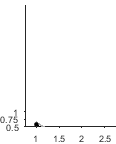

[WTcloseGroup, WTfarGroup, VG3closeGroup, VG3farGroup] = SGNdistCorr();

figure;
meanWTclose = mean(WTcloseGroup);
sterrWTclose = std(WTcloseGroup,[],2)/sqrt(size(WTcloseGroup,2));
meanWTfar = mean(WTfarGroup);
sterrWTfar = std(WTfarGroup,[],2)/sqrt(size(WTfarGroup,2));
meanVG3close = mean(VG3closeGroup);
sterrVG3close = std(VG3closeGroup,[],2)/sqrt(size(VG3closeGroup,2));
meanVG3far = mean(VG3farGroup);
sterrVG3far = std(VG3farGroup,[],2)/sqrt(size(VG3farGroup,2));
WTn = size(WTcloseGroup,2);
VG3n = size(VG3closeGroup,2);

line([1*ones(1,WTn); 1.5*ones(1,WTn)], [WTcloseGroup;WTfarGroup],'Color',[0.7 0.7 0.7]); hold on;
line([2*ones(1,VG3n); 2.5*ones(1,VG3n)], [VG3closeGroup;VG3farGroup],'Color',[0.7 0.7 0.7]);
errorbar(1, meanWTclose, sterrWTclose,'LineStyle', 'none','Color','k','CapSize',0,'Marker','.','MarkerSize',10);
errorbar(1.5, meanWTfar, sterrWTfar,'LineStyle', 'none','Color','k','CapSize',0,'Marker','.','MarkerSize',10);
errorbar(2, meanVG3close, sterrVG3close,'LineStyle', 'none','Color','r','CapSize',0,'Marker','.','MarkerSize',10);
errorbar(2.5, meanVG3far, sterrVG3far,'LineStyle', 'none','Color','r','CapSize',0,'Marker','.','MarkerSize',10);
line([1; 1.5], [meanWTclose;meanWTfar],'Color','k');
line([2; 2.5], [meanVG3close;meanVG3far],'Color','r');

xlim([.75 2.75]);
ylim([0 1]);
yticks([0:.25:1]);
figQuality(gcf, gca, [1.2 1.5]);
set(gca,'LooseInset',get(gca,'TightInset'));
export_fig('.\EPS Panels\corrDistance_group.eps',gcf);

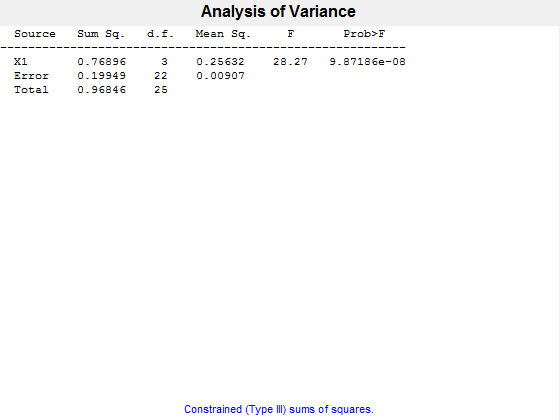


%%stats
group = [ones(WTn,1); 2*ones(WTn,1); 3*ones(VG3n,1); 4*ones(VG3n,1)];
[p,t,stats] = anovan([WTcloseGroup';WTfarGroup';VG3closeGroup';VG3farGroup'], group);

c =     1.0000    2.0000    0.2842    0.4515    0.6187    0.0000
    1.0000    3.0000    0.1524    0.3031    0.4539    0.0001
    1.0000    4.0000    0.3144    0.4652    0.6159    0.0000
    2.0000    3.0000   -0.2991   -0.1483    0.0024    0.0549
    2.0000    4.0000   -0.1370    0.0137    0.1644    0.9942
    3.0000    4.0000    0.0298    0.1620    0.2942    0.0126


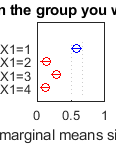

c = multcompare(stats)

## SGN Distance Correlation

function [WTcloseGroup, WTfarGroup, VG3closeGroup, VG3farGroup] = SGNdistCorr()
    dname = '.\Data\In Vitro Experiments';
    list = loadFileList([dname '\WT + NBQX\*\*V3.mat']);
    csvlist = loadFileList([dname '\WT + NBQX\*\*CM.csv']);
    
    
    for i = 1:size(csvlist,1)
        load(list{i});
        keepTrace = int8(find([eventStruct.SGN(:).keepTrace]));
    
        SGNsignals = [eventStruct.SGN(keepTrace).dFoF];
        SGNsignals = SGNsignals(1:600,:);
        corrMat = corrcoef(SGNsignals);
        
        csvR = csvread(csvlist{i},1,1);
        csvR = csvR(keepTrace',:);
        pts = csvR;
        
        distances = [];
        for j=1:size(csvR,1)
            pt = csvR(j,:); 
            distances(:,j) = sqrt((pts(:,1)-pt(:,1)).^2+(pts(:,2)-pt(:,2)).^2);
        end
        
        [b, ordered] = sort(distances,'ascend');
        
        meanNeighbors = 5;
        close = [];
        far = [];
        for j=1:size(csvR,1)
            close(:,j) = corrMat(j,ordered(2:meanNeighbors+1,j));
            far(:,j) = corrMat(j,ordered(end-meanNeighbors:end,j));
        end
        
        WTcloseGroup(i) = mean(mean(close));
        WTfarGroup(i) = mean(mean(far));
        
    end
    
    %% dname = 'M:\Bergles Lab Data\Projects\In Vivo Imaging and VG3 Paper\In Vitro Experiments';
    list = loadFileList([dname '\VG3KO + NBQX + BBE\*\*V3.mat']);
    csvlist = loadFileList([dname '\VG3KO + NBQX + BBE\*\*CM.csv']);
    
    
    for i = 1:size(csvlist,1)
        load(list{i});
        keepTrace = int8(find([eventStruct.SGN(:).keepTrace]));
    
        SGNsignals = [eventStruct.SGN(keepTrace).dFoF];
        SGNsignals = SGNsignals(1:600,:);
        corrMat = corrcoef(SGNsignals);
        
        csvR = csvread(csvlist{i},1,1);
        csvR = csvR(keepTrace',:);
        pts = csvR;
        
        distances = [];
        for j=1:size(csvR,1)
            pt = csvR(j,:); 
            distances(:,j) = sqrt((pts(:,1)-pt(:,1)).^2+(pts(:,2)-pt(:,2)).^2);
        end
        
        [b, ordered] = sort(distances,'ascend');
        
        meanNeighbors = 5;
        close = [];
        far = [];
        for j=1:size(csvR,1)
            close(:,j) = corrMat(j,ordered(2:meanNeighbors+1,j));
            far(:,j) = corrMat(j,ordered(end-meanNeighbors:end,j));
        end
        
        VG3closeGroup(i) = mean(mean(close));
        VG3farGroup(i) = mean(mean(far));
        
    end
end
 
 

